Problem 5 Homework 2

(a)

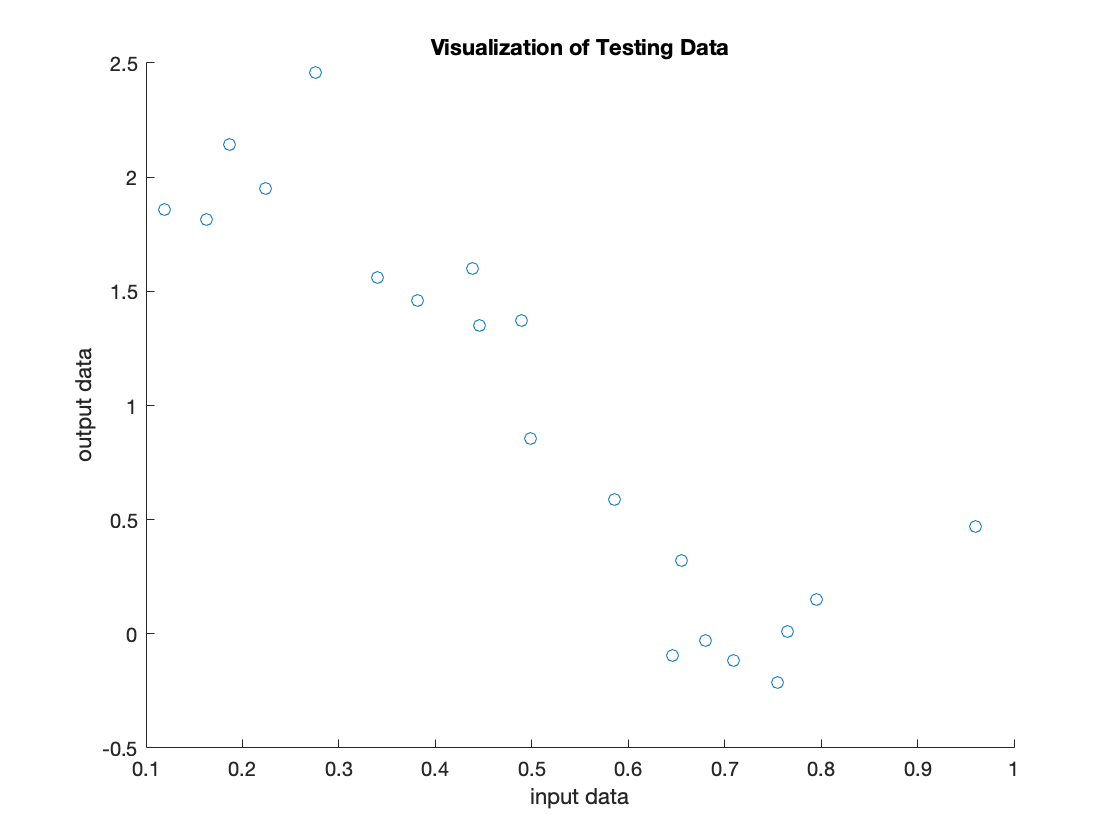

traindata = readtable("regression_train.csv");
testdata = readtable("regression_test.csv");

figure(1);
hold on;
train_in = traindata{:,1};
train_out = traindata{:,2};
scatter(train_in, train_out);
title("Visualization of Training Data");
xlabel("input data");
ylabel("output data");

figure(2);
test_in = testdata{:,1};
test_out = testdata{:,2};
scatter(test_in, test_out);
title("Visualization of Testing Data");
xlabel("input data");
ylabel("output data");

For these two scatter plots, it seems like the training one is less like a linear graph, and more like a cubic or a sinusoid. If we forced linear regression, it would seem like the fit wouldn't be that good and some points would be far away from the line.

However, for the testing data plot, it seems like it does fit the shape of a line a lot better.

(b)

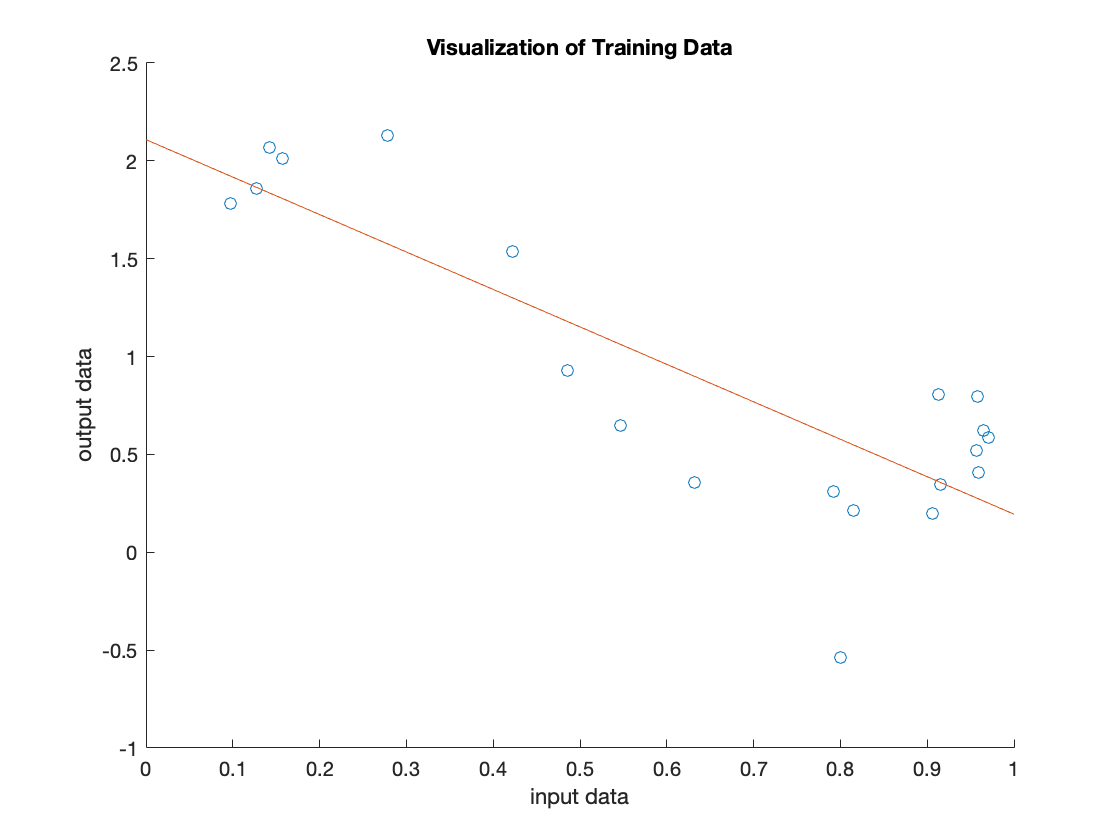

n = size(traindata, 1);
y = train_out;
X = [ones(n, 1) train_in];
ws = (X' * X)^(-1) * X' * y;
J = norm(X * ws - y)^2;
xval = (0:0.01:1);
yval = ws(1) + ws(2) * xval;
figure(1);
plot(xval, yval);
hold off;

(c)

for eta = [0.05, 0.001, 0.0001, 0.00001]
    w = zeros(2, 1);
    Jprev = norm(X * w - y);
    for iters = 1:10000
        w1 = w(1) - eta * (X * w - y)' * X(:, 1);
        w2 = w(2) - eta * (X * w - y)' * X(:, 2);
        w = [w1; w2];
        J = norm(X * w - y)^2;
        if abs(J - Jprev) < 0.0001
            break
        end
        Jprev = J;
    end
    eta
    iters
    J
end

eta = 0.0500

iters = 66

J = 3.2606

eta = 1.0000e-03

iters = 2009

J = 3.2947

eta = 1.0000e-04

iters = 10000

J = 3.8878

eta = 1.0000e-05

iters = 10000

J = 11.5685

The lower the learning rate, $\eta$, the more iterations we need until completion. In addition, it seems like the final value of J is higher for lower $\eta$.

(d)

eta = 0.05

eta = 0.0500

w = zeros(2, 1);
J = norm(X * w - y)^2;
f = 3;
w

w =      0
     0


J

J = 26.3134

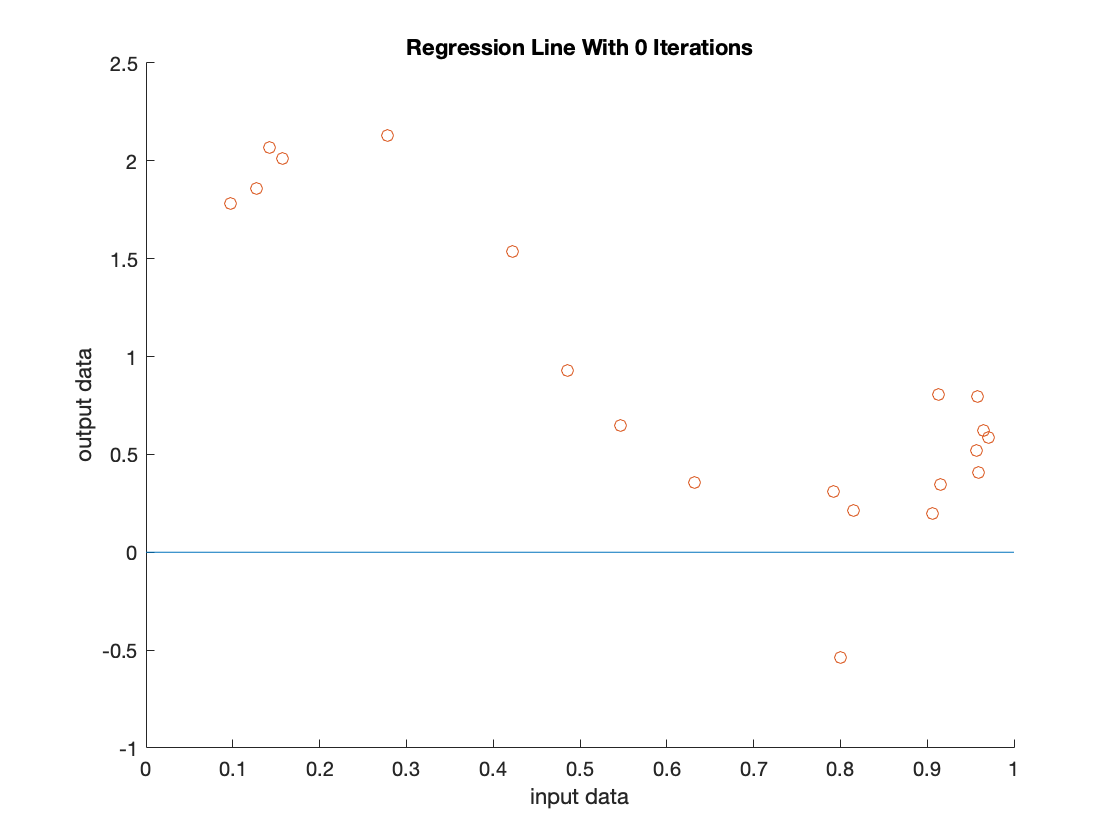

figure(f);
hold on;
xval = (0:0.01:1);
yval = w(1) + w(2) * xval;
plot(xval, yval);
xlabel("input data");
ylabel("output data");
title(sprintf("Regression Line With %d Iterations", 0))
scatter(train_in, train_out);

w =     1.3580
   -0.8289


J = 5.7519

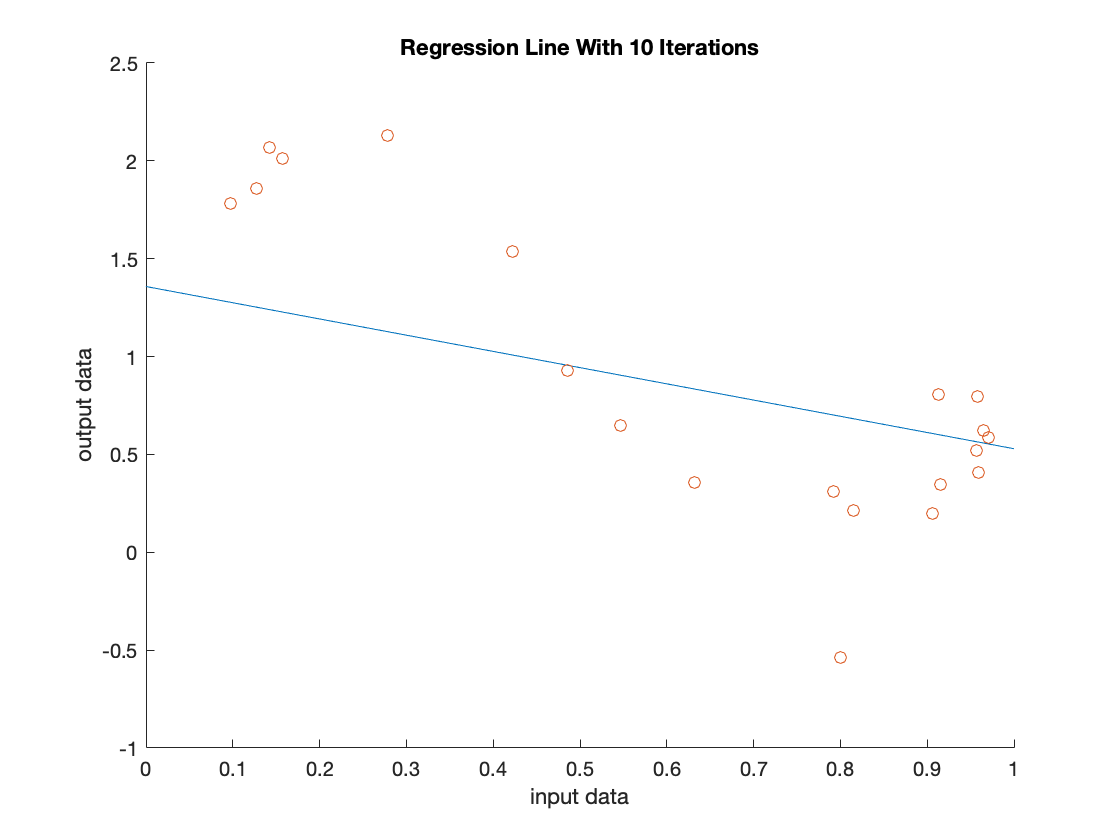

w =     1.7515
   -1.3976


J = 3.8237

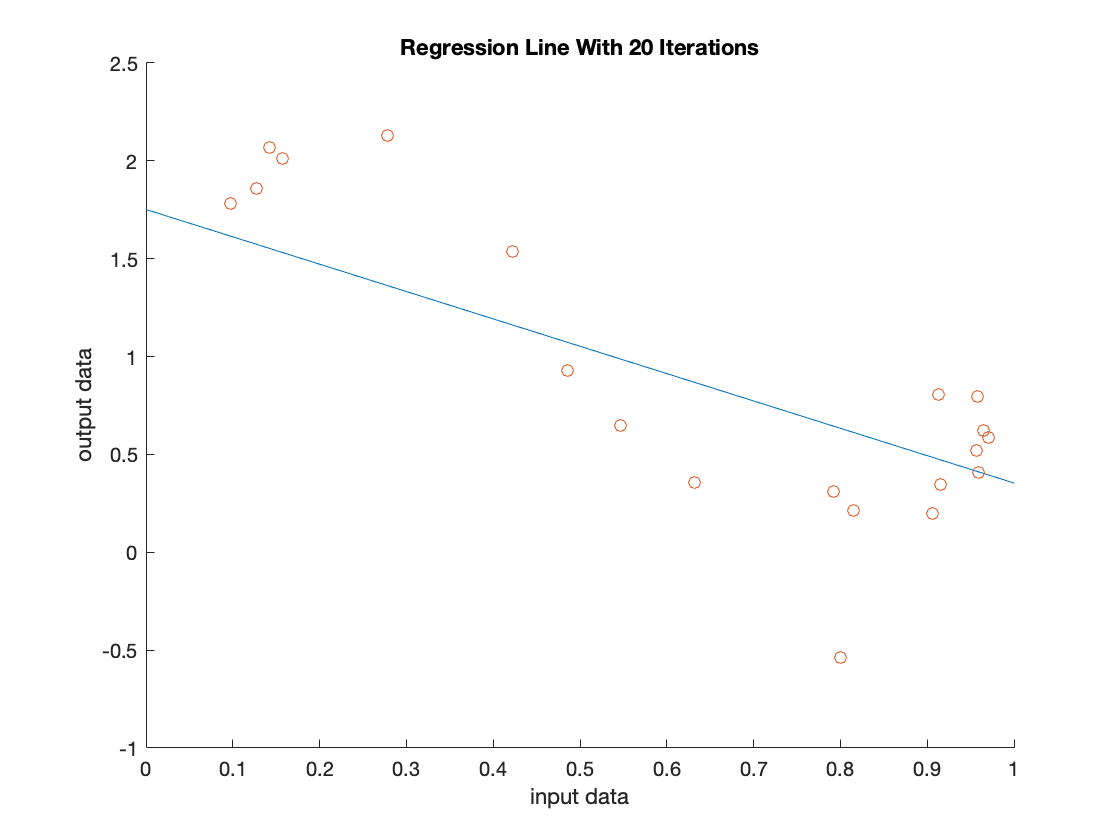

w =     1.9386
   -1.6682


J = 3.3875

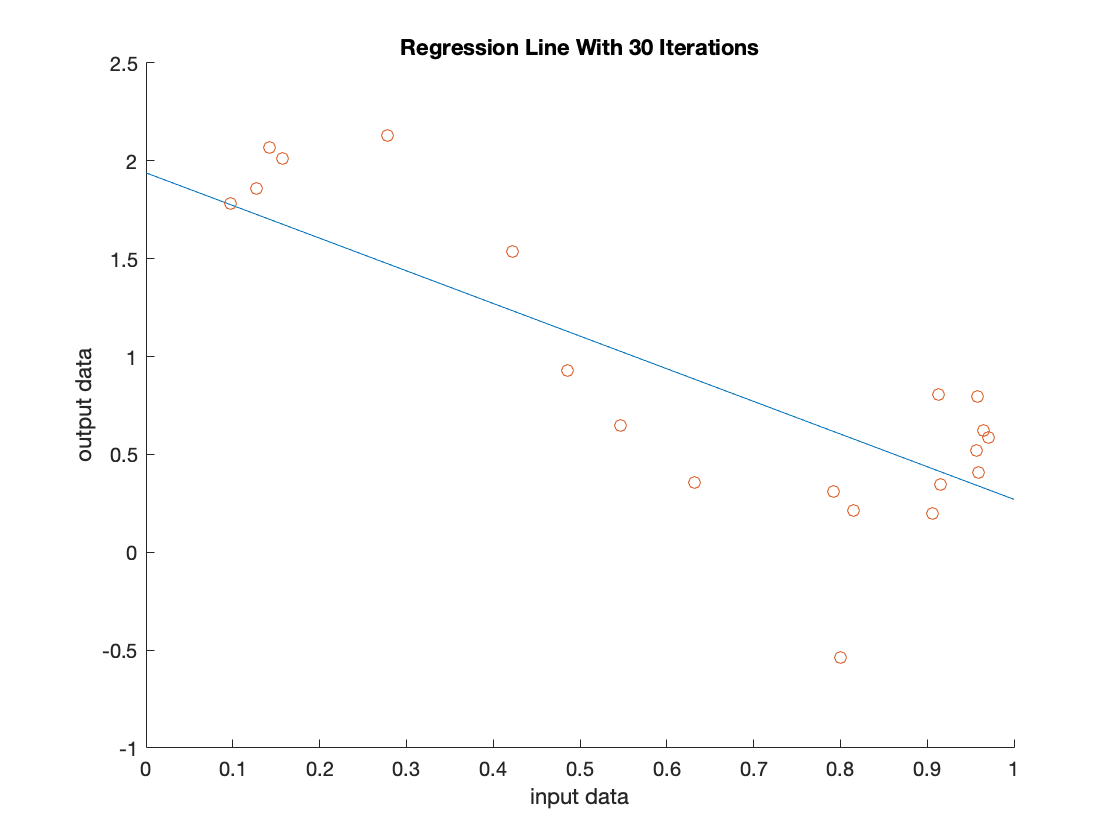

w =     2.0276
   -1.7969


J = 3.2888

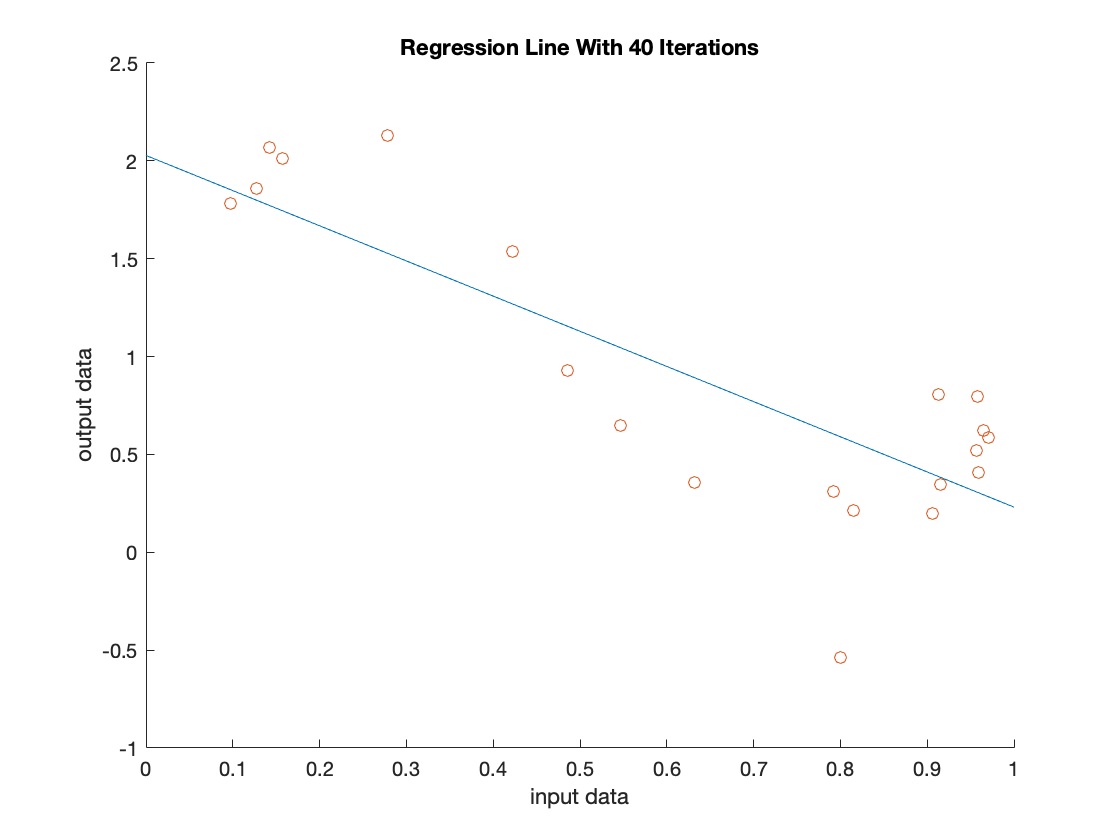

f = f + 1;

for iters = 1:40
    w1 = w(1) - eta * (X * w - y)' * X(:, 1);
    w2 = w(2) - eta * (X * w - y)' * X(:, 2);
    w = [w1; w2];
    J = norm(X * w - y)^2;
    if mod(iters, 10) == 0
        w
        J
        figure(f);
        hold on;
        xval = (0:0.01:1);
        yval = w(1) + w(2) * xval;
        plot(xval, yval);
        xlabel("input data");
        ylabel("output data");
        title(sprintf("Regression Line With %d Iterations", iters))
        scatter(train_in, train_out);
        f = f + 1;
    end
end

Over time, the line gets closer and closer to fitting the data, which is what we expect. The fitted lines originally have 0 slope but get closer and closer to what I had in (b).

(ei)

ntrain = size(traindata, 1);
ytrain = train_out;
xtrain = train_in;
Xtrain = ones(ntrain, 1);

ntest = size(testdata, 1);
ytest = test_out;
xtest = test_in;
Xtest = ones(ntest, 1);

Etrain_rms = [];
Etest_rms = [];

for m = 0:10
    wstrain = (Xtrain' * Xtrain)^(-1) * Xtrain' * ytrain;
    m
    Jtest = norm(Xtest * wstrain - ytest)^2
    Jtrain = norm(Xtrain * wstrain - ytrain)^2;
    
    Etrain_rms(end + 1) = sqrt(Jtrain / n);
    Etest_rms(end + 1) = sqrt(Jtest / n);
    
    Xtrain = [Xtrain xtrain];
    xtrain = xtrain .* xtrain;
    Xtest = [Xtest xtest];
    xtest = xtest .* xtest;
end

m = 0

Jtest = 14.6448

m = 1

Jtest = 5.4816

m = 2

Jtest = 4.0882

m = 3

Jtest = 1.0160

m = 4

Jtest = 0.8068

m = 5

Jtest = 0.7795

m = 6

Jtest = 0.8481

m = 7

Jtest = 1.0131

m = 8

Jtest = 1.0005

m = 9

Jtest = 1.0088

m = 10

Jtest = 0.9871

Best model seems like the one where m = 5, as that one fits the test data the best. We'll calculate Erms for this value of m.

fprintf("Optimal E_RMS for training data: %f\n", Etrain_rms(6));

Optimal E_RMS for training data: 0.194756


fprintf("Optimal E_RMS for test data: %f\n", Etest_rms(6));

Optimal E_RMS for test data: 0.197419


(eii)

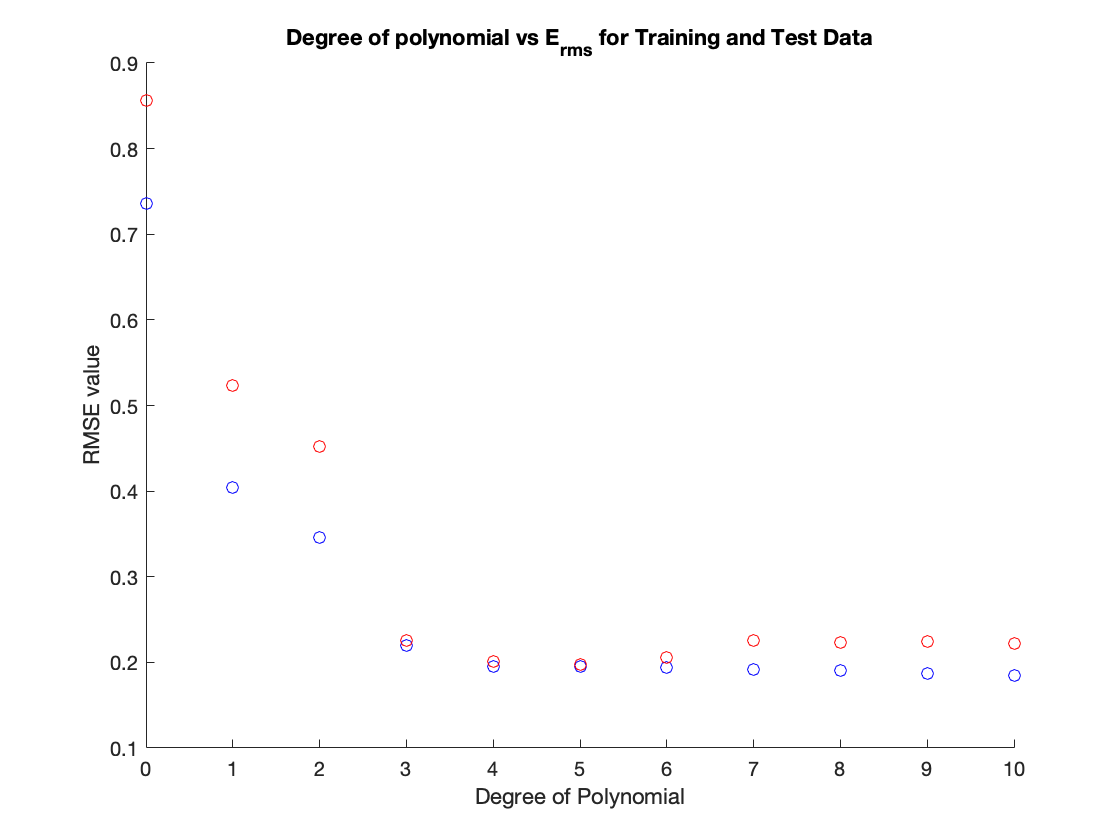

xval = (0:1:10);
y1val = Etrain_rms;
y2val = Etest_rms;
figure(20);
hold on;
scatter(xval, y1val, "blue");
scatter(xval, y2val, "red");
title("Degree of polynomial vs E_{rms} for Training and Test Data");
xlabel("Degree of Polynomial");
ylabel("RMSE value");

Red is the test data, and Blue is the training data RMSE values.

(eiii)

I think that the degree of 4 or 5 best fits the data. 5 is where the values for test and train are closest together, but I think the individual values of 4 are lower. There is definitely overfitting in the higher degree values, because the testing data has much higher values of Erms than the training data. If there was overfitting, then while the fit for training might be very low, the fit for test would not be because of overfitting. We can see the spread between test and train Erms values as degree gets higher. For 4 and 5 though they are very close!